import plotFrame.*;

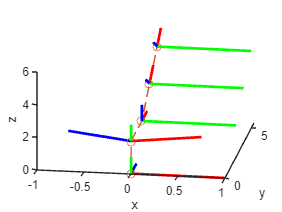

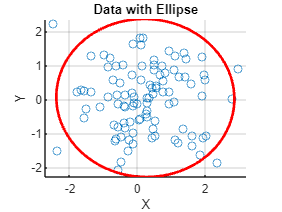

clear all;

l01 = 2;
l12 = 2;
l23 = 2;
l3E = 2;

phi1 = pi/4;
phi2 = pi/4;
phi3 = pi/4;

H01 = DHMatrix(0, l01, 0, phi1);
H12 = DHMatrix(l12, 0, pi/2, phi2);
H23 = DHMatrix(l23, 0, 0, phi3);
T34 = DHMatrix(l3E, 0, 0, 0);

H02 = H01*H12;
H03 = H01*H12*H23;

fp0 = [0; 0; 0; 1];
fp1 = H01*fp0;
fp2 = H02*fp0;
fp3 = H03*fp0;
fp4 = H03*T34*fp0;

points = [fp0, fp1, fp2, fp3, fp4];

hold on;
plotFrame(eye(4));
plotFrame(H01);
plotFrame(H02);
plotFrame(H03);
plotFrame(H03*T34);
plot3(points(1, :), points(2, :), points(3, :), '--o');
view([9, 30]);
xlabel('x');
ylabel('y');
zlabel('z');
hold off;

function matrix = DHMatrix(a, d, alpha, theta)
     % function to create the matrix from the DH table row
    matrix = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);
              sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
              0 sin(alpha) cos(alpha) d;
              0 0 0 1
             ];
end

function plotFrame(T, varargin)
    if ~isempty(varargin)
        k = varargin{1};
    else
        k = 1;
    end

    x = [k 0 0 1]';
    y = [0 k 0 1]';
    z = [0 0 k 1]';
    
    Op = T * [0 0 0 1]';
    xp = T * x;
    yp = T * y;
    zp = T * z;
    
    plot3([Op(1) xp(1)], [Op(2) xp(2)], [Op(3) xp(3)], 'r', 'LineWidth', 2)
    % hold on
    plot3([Op(1) yp(1)], [Op(2) yp(2)], [Op(3) yp(3)], 'b', 'LineWidth', 2)
    plot3([Op(1) zp(1)], [Op(2) zp(2)], [Op(3) zp(3)], 'g', 'LineWidth', 2)
    % hold off
end

function [a, b] = prova(m1, m2)
    [a, b] = m1, m2;
end